clc; clear; close all; format compact

% Global Parameters
global ThrustTime ThrustForce rho S cl_alpha le I mPropG25W tburnG25W g_accel C_D
tT = struct2array(load("Aerotech_G25W.mat"));
ThrustTime = tT(:,1); ThrustForce = tT(:,2);
g_accel = 9.81; %m/s^2
rho = 1.225; %kg/m^3
D = 3.1*(2.54/100); %m
S = pi/4 * D^2; %m^2
cl_alpha = 2*pi; %rad^(-1)
le = 18*(2.54/100); %m
I = 1.2; %kg-m^2
tburnG25W = 5.3; %s
mPropG25W = (62.5*1E-3); %kg
C_D = 0.75; %unitless

%initial conditions
x0 = 0; %m
z0 = 0; %m
theta0 = pi/2 - deg2rad(0); %rad
xdot0 = 0; %m/s
zdot0 = 0; %m/s
thetadot0 = 0; %rad/s
m0 = 1.5; %kg
i0 = deg2rad(0.65); %rad

state0 = [x0; 
          z0;
          theta0;
          xdot0;
          zdot0;
          thetadot0;
          m0;
          i0];


%ODE45 implementation
tspan = [0 20]; %s
RelTol = 1E-4; MaxStep = 1E-3; %s
options = odeset('RelTol',RelTol,'MaxStep',MaxStep);
[t,state] = ode45(@rates,tspan,state0,options);


% extract values from state array and trim end values with z<0
xi = state(:,1); %m
zi = state(:,2); %m
theta = state(:,3); %rad
xdoti = state(:,4); %m/s
zdoti = state(:,5); %m/s
thetadot = state(:,6); %rad/s
m = state(:,7); %kg
i = state(:,8); %rad



% compute state derivative values

indices=find(zi>-0.2);

xddoti=zeros(length(t),1);
zddoti=zeros(length(t),1);
thetaddot=zeros(length(t),1);
mdot=zeros(length(t),1);
idot=zeros(length(t),1);

for ctr = 1:length(t)
    stateDot = rates(t(ctr),state(ctr,:));

    xddoti(ctr) = stateDot(4); %m/s^2
    zddoti(ctr) = stateDot(5); %m/s^2
    thetaddot(ctr) = stateDot(6); %rad/s
    mdot(ctr) = stateDot(7); %kg/s
    idot(ctr) = stateDot(8); %rad/s
end

Trajectory graph

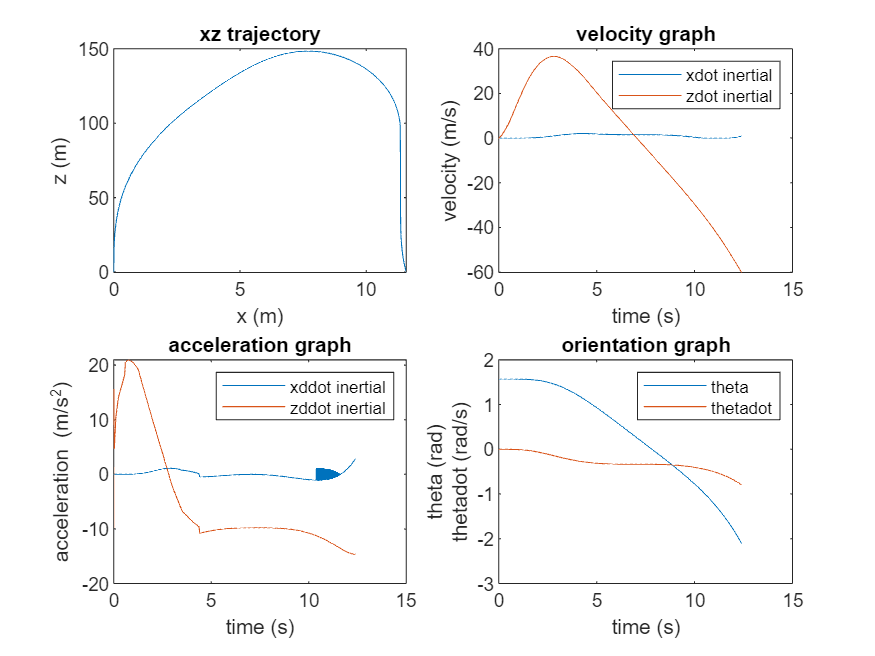

figure
subplot(2,2,1)
plot(xi(indices),zi(indices)); title ('xz trajectory'); xlabel('x (m)'); ylabel('z (m)');

% Velocity graph
subplot(2,2,2)
plot(t(indices),xdoti(indices),t(indices),zdoti(indices)); title('velocity graph'); xlabel('time (s)'); ylabel('velocity (m/s)'); legend('xdot inertial','zdot inertial');

% Acceleration graph
subplot(2,2,3)
plot(t(indices),xddoti(indices),t(indices),zddoti(indices)); title('acceleration graph'); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); legend('xddot inertial','zddot inertial');

% Orientation graph
subplot(2,2,4)
plot(t(indices),theta(indices),t(indices),thetadot(indices)); title('orientation graph'); xlabel('time (s)'); ylabel({'theta (rad)','thetadot (rad/s)'}); legend('theta','thetadot')

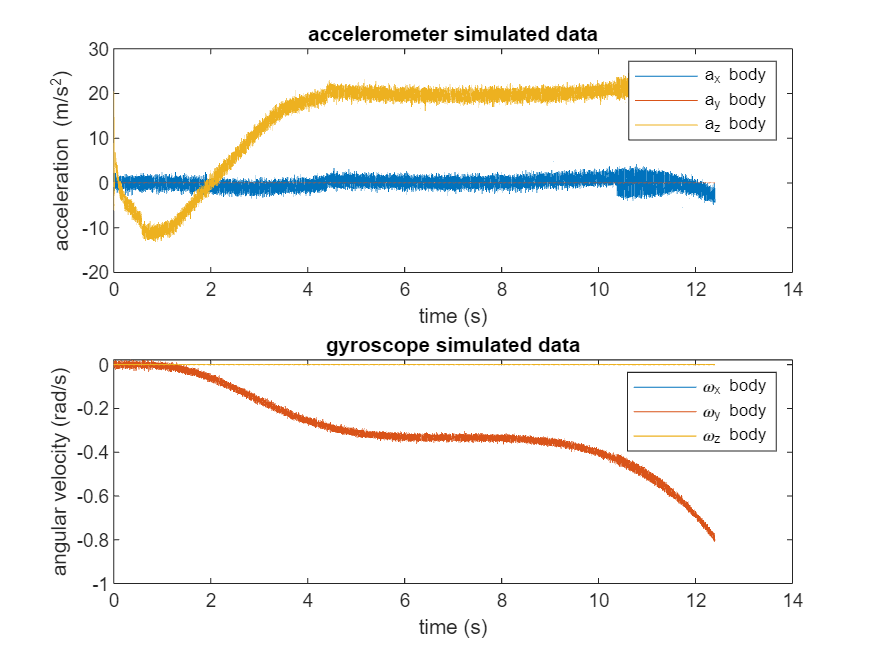

%Create IMU data
IMU = imuSensor('accel-gyro-mag');
acc = [xddoti zeros(size(xddoti)) zddoti]; %m/s
angVel = [zeros(size(thetadot)) thetadot zeros(size(thetadot))]; %rad/s
IMU.Accelerometer.NoiseDensity = [1 0 1]*0.1;
IMU.Gyroscope.NoiseDensity = [0 1 0]*0.001;
[accelReadings,gyroReadings] = IMU(acc,angVel);
figure
subplot(2,1,1)
plot(t(indices),accelReadings(indices,1),t(indices),accelReadings(indices,2),t(indices),accelReadings(indices,3))
title('accelerometer simulated data'); xlabel('time (s)'); ylabel('acceleration (m/s^2)'); legend('a_x body','a_y body','a_z body')
subplot(2,1,2)
plot(t(indices),gyroReadings(indices,1),t(indices),gyroReadings(indices,2),t(indices),gyroReadings(indices,3))
title('gyroscope simulated data'); xlabel('time (s)'); ylabel('angular velocity (rad/s)'); legend('\omega_x body','\omega_y body','\omega_z body')

OLTF =
 
   3.848
  -------
  1.5 s^2
 
Continuous-time transfer function.
Model Properties
CLTF =
 
       3.848
  ---------------
  1.5 s^2 + 3.848
 
Continuous-time transfer function.


numCLTF =          0         0    3.8485


denCLTF =     1.5000         0    3.8485


rts =    0.0000 + 1.6018i
   0.0000 - 1.6018i


OLTF_C =
 
  1.5e04 s^2 + 5.249e06 s + 4.593e08
  ----------------------------------
               1.5 s^3
 
Continuous-time transfer function.
Model Properties
CLTF_C =
 
       1.5e04 s^2 + 5.249e06 s + 4.593e08
  --------------------------------------------
  1.5 s^3 + 1.5e04 s^2 + 5.249e06 s + 4.593e08
 
Continuous-time transfer function.


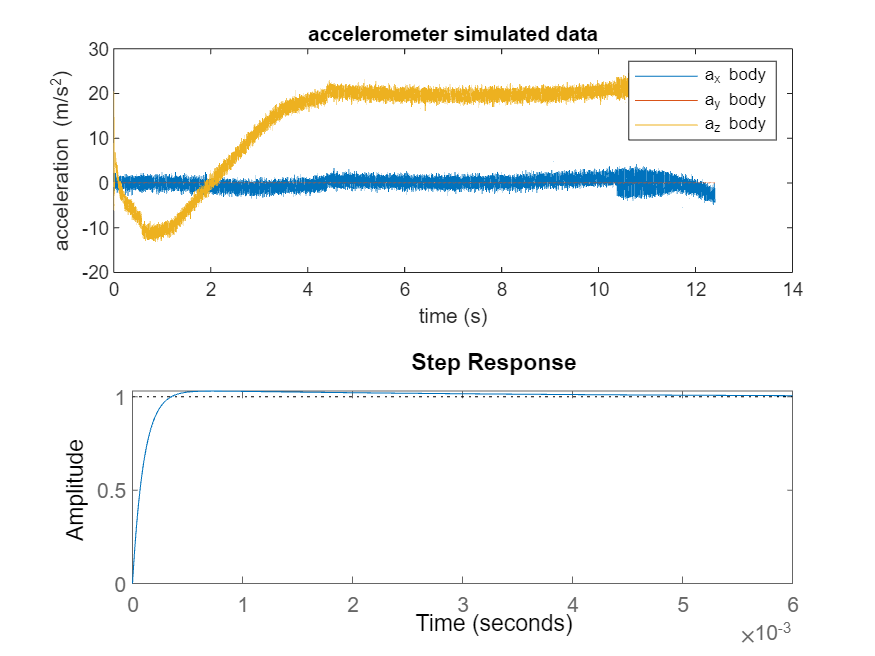

numCLTF_C = 1.0e+08 *

         0    0.0001    0.0525    4.5931


denCLTF_C = 1.0e+08 *

    0.0000    0.0001    0.0525    4.5931


controller_pitch

fitresult =      Shape-preserving (pchip) interpolant:
       fitresult(x) = piecewise polynomial computed from p
       with pchip extrapolation
       where x is normalized by mean 30.23 and std 20.93
     Coefficients:
       p = coefficient structure

gof = struct with fields:
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN

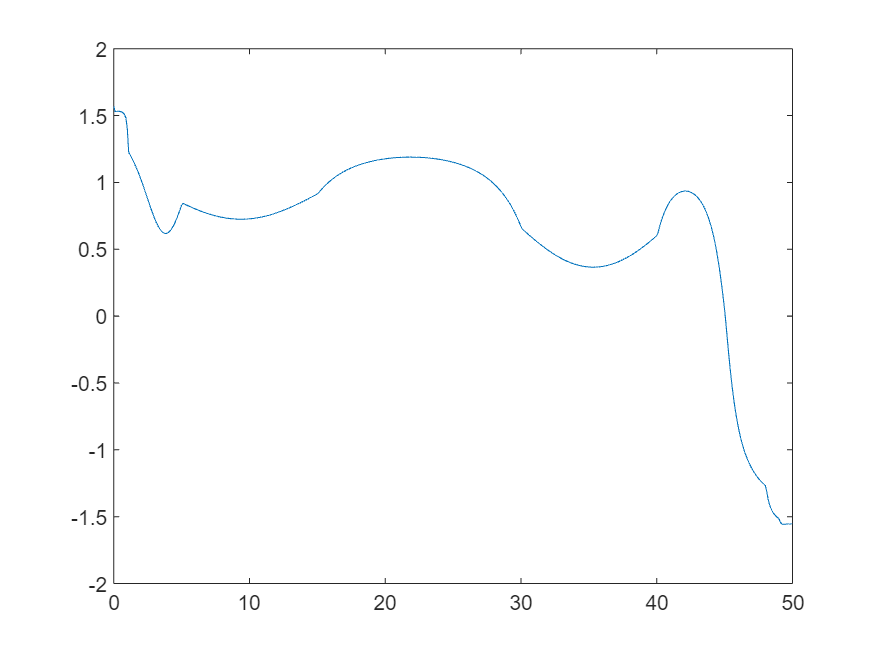

ans = 0.9593

Pitch_Values

function stateDot = rates(t,state)

    global ThrustTime ThrustForce rho S cl_alpha le I mPropG25W tburnG25W g_accel C_D;
    x = state(1); %m
    z = state(2); %m
    theta = state(3); %rad
    xdot = state(4); %m/s
    zdot = state(5); %m/s
    thetadot = state(6); %rad/s
    m = state(7); %kg
    i = state(8); %rad

% compute thrust and freestream velocity
    T = interp1(ThrustTime,ThrustForce,t,'linear',0); %N
    v_inf = sqrt(xdot^2 + zdot^2); %m/s

% compute elevator force
    Fe = (0.5*rho*v_inf^2)*S*cl_alpha*i; %N
    thetaddot = -Fe*le/I;

%compute drag value
    D = (0.5*rho*v_inf^2)*C_D*S;

% assign value to g based on whether rocket has left the pad yet
    if (T>g_accel*m)||(t<tburnG25W)
        g = g_accel; %m/s^2
    else
        if (t>tburnG25W)
            g=g_accel; %m/s^2
        else
        g=0;
        end
    end

% determine direction of drag in x and z directions
    if xdot>=0
        signD_x = +1; %unitless
    else
        signD_x = -1; %unitless
    end    
    xddot = (T-D*signD_x)*cos(theta)/m; %m/s^2

    if zdot>=0
        signD_z = +1; %unitless
    else
        signD_z = -1; %unitless
    end
    zddot = (T-D*signD_z)*sin(theta)/m - g; %m/s^2

%evaluate fin incidence angle i
% insert controller and transfer function between i and theta here

idot = 0;

%evaluate mdot
    if t<=tburnG25W
        mdot = -mPropG25W/tburnG25W; %kg/s
    else
        mdot = 0;
    end

%output state derivative
    stateDot = [xdot;
                zdot;
                thetadot;
                xddot;
                zddot;
                thetaddot;
                mdot;
                idot;
                ];
end